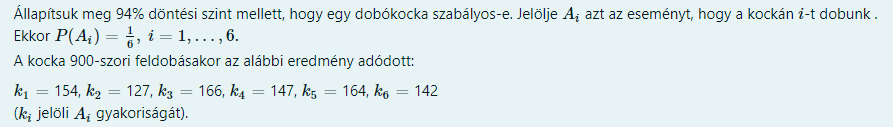

Miért χ2-próba? 

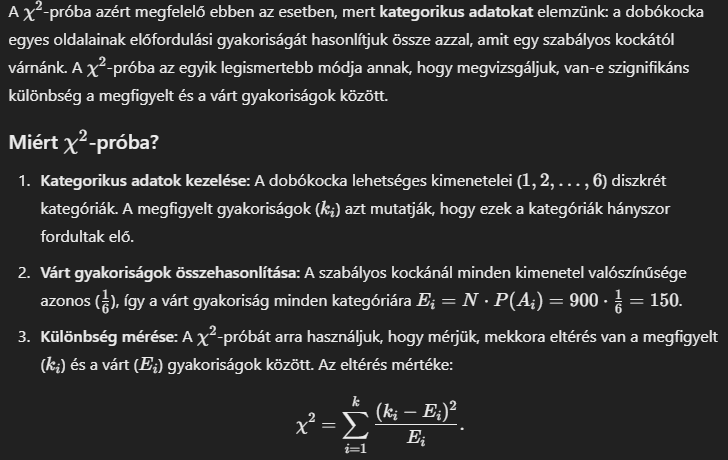

% Adatok
observed = [154, 127, 166, 147, 164, 142]; % Megfigyelt gyakoriságok
N = 900; % Dobások száma
p = 1/6; % Valószínűség szabályos kocka esetén
expected = N * p * ones(1, 6); % Várt gyakoriságok
alpha = 0.06; % Szignifikancia szint

% Próbastatisztika számítása
chi2_stat = sum((observed - expected).^2 ./ expected)

chi2_stat = 7.1333

% [h,~,stats]=chi2gof(1:6,900,observed,alpha)

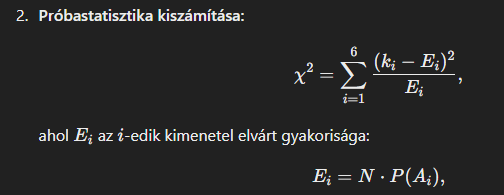


% Kritikus érték számítása
df = length(observed) - 1; % Szabadságfok
chi2_critical = chi2inv(1 - alpha, df);


% Döntés
decision = chi2_stat > chi2_critical; % 0: elfogadjuk, 1: elvetjük

% Eredmények kiírása
fprintf('Próbastatisztika értéke: %.3f\n', chi2_stat);

Próbastatisztika értéke: 7.133


fprintf('Kritikus érték: %.3f\n', chi2_critical);

Kritikus érték: 10.596


fprintf('Döntés (0: elfogadjuk, 1: elvetjük): %d\n', decision);

Döntés (0: elfogadjuk, 1: elvetjük): 0


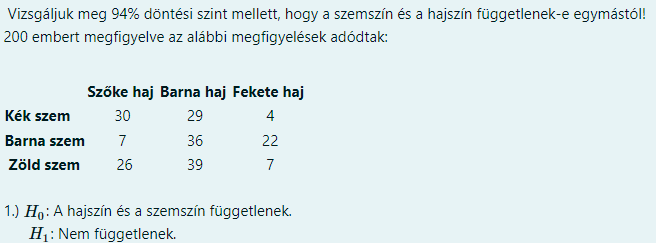

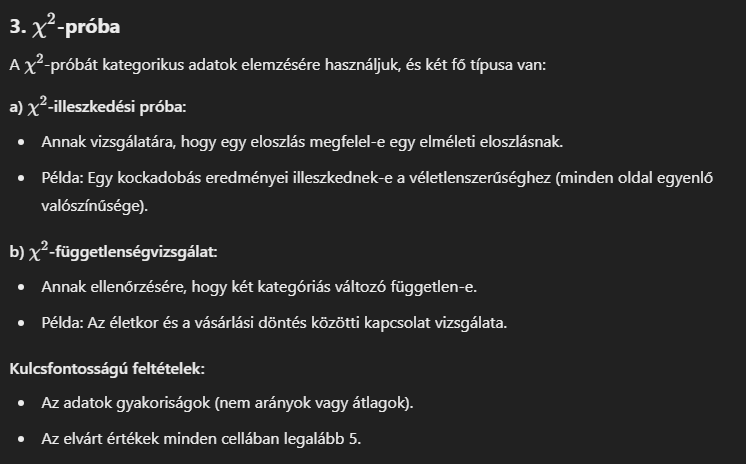

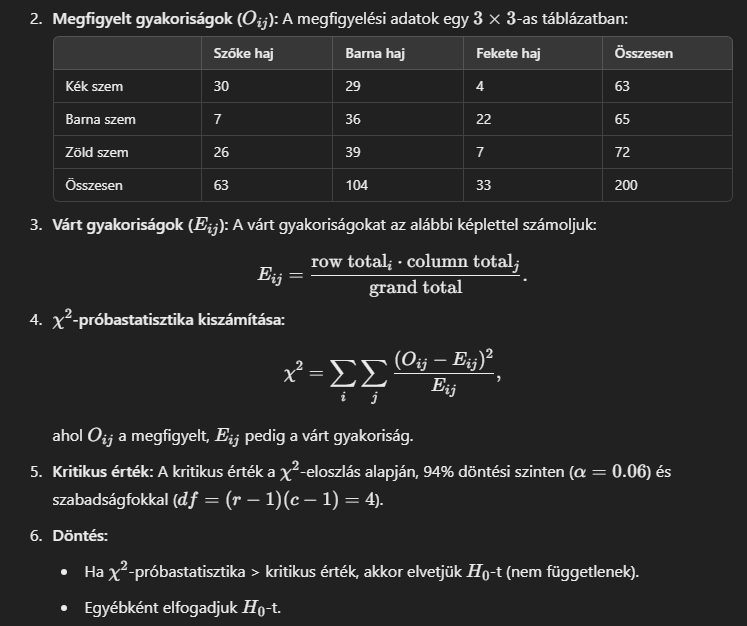

% Megfigyelt gyakoriságok (O_ij)
observed = [29, 25, 8;
            11,  53, 18;
            24, 25, 7];

%expected = (row * col) / grand_total

% Összesítések
row_totals = sum(observed, 2); % Sorösszegek
col_totals = sum(observed, 1); % Oszlopösszegek
grand_total = sum(observed,'all'); % Teljes minta

% Várt gyakoriságok (E_ij)
expected = (row_totals * col_totals) / grand_total

expected =    19.8400   31.9300   10.2300
   26.2400   42.2300   13.5300
   17.9200   28.8400    9.2400



% Próbastatisztika kiszámítása
chi2_stat = sum((observed - expected).^2 ./ expected, 'all')

chi2_stat = 22.4112

% % [h,~,X2] = chi2cont(observed,alpha)

Unrecognized function or variable 'chi2cont'.

% Kritikus érték
alpha = 0.03; % Szignifikancia szint
df = (size(observed, 1) - 1) * (size(observed, 2) - 1); % Szabadságfok
chi2_critical = chi2inv(1 - alpha, df);

% Döntés
decision = chi2_stat > chi2_critical; % 0: elfogadjuk, 1: elvetjük

% Eredmények kiírása
fprintf('Próbastatisztika értéke: %.3f\n', chi2_stat);
fprintf('Kritikus érték: %.3f\n', chi2_critical);
fprintf('Döntés (0: elfogadjuk, 1: elvetjük): %d\n', decision);



observed=[128 166 144 174 157 131];
p=1/6;
alpha=0.06;
dt=length(observed)-1;
N=900;
expected=N*p*ones(1,6);

chi2stat=sum((observed-expected).^2./expected)
chi2crit=chi2inv(1-alpha,dt)